clc; clear all; close all;
run('variableLoader.m')
%INPUTS
sim('inputs_siso.slx');
load('doublet.mat')
input = doublet;

# Elevator input - short period mode(5secs)

paramStruct.StopTime = "5";

## elevator to pitch rate

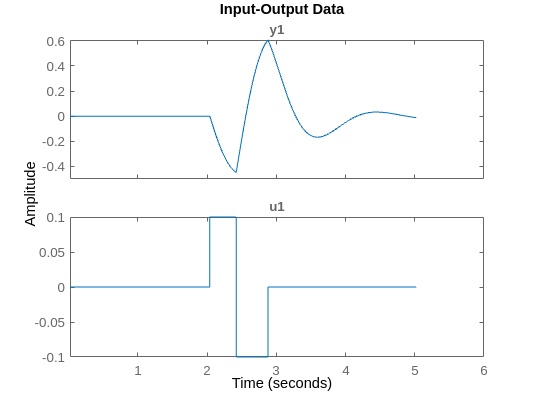

out = sim('el_pr',paramStruct);
u = out.elevator;
y = squeeze(out.pitch_rate);
data = iddata(y,u,0.02);
plot(data)

sys_el_pr= tfest(data, 3, 2)

sys_el_pr =
  From input "u1" to output "y1":
      -18.32 s^2 - 48.76 s + 15.65
  ------------------------------------
  s^3 + 3.434 s^2 + 16.62 s + 3.13e-14
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 98.58%                   
FPE: 6.861e-06, MSE: 6.386e-06                   
 
Model Properties


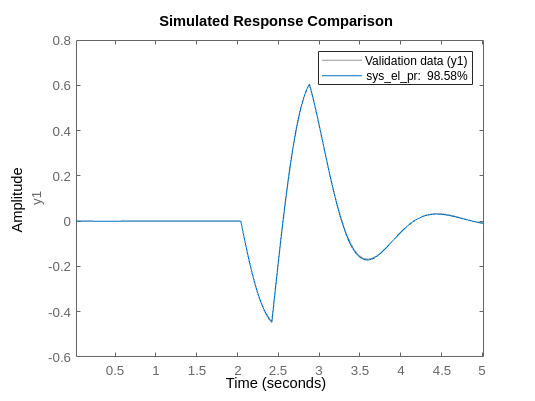

compare(data,sys_el_pr)

## elevator to aoa

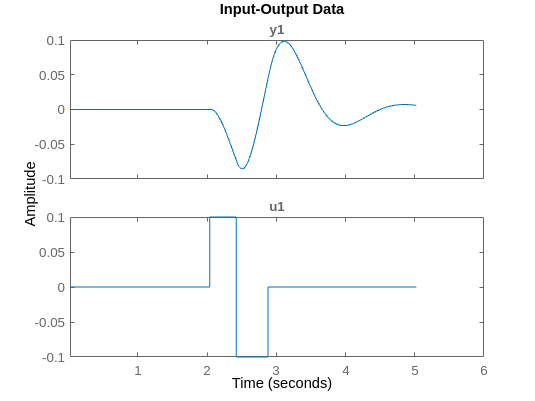

out = sim('el_a',paramStruct);
u = out.elevator;
y = squeeze(out.aoa)-alpha_trim;
data = iddata(y,u,0.02);
plot(data)

sys_el_a= tfest(data, 3, 2)

sys_el_a =
  From input "u1" to output "y1":
    0.3069 s^2 + 17.2 s - 2509
  ------------------------------
  s^3 + 140 s^2 + 470.9 s + 2214
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 98.67%                   
FPE: 2.327e-07, MSE: 2.166e-07                   
 
Model Properties


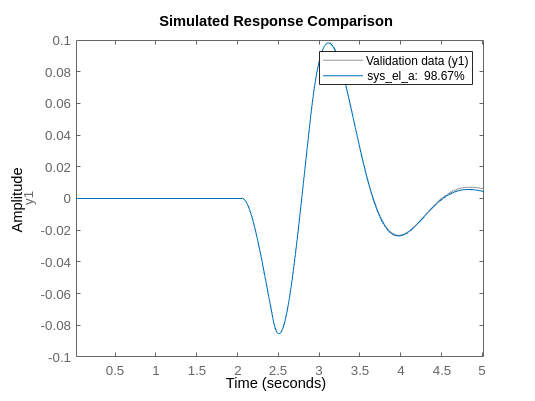

compare(data,sys_el_a)

# Elevator input - phugoid mode(20secs)

paramStruct.StopTime = "20";

## elevator to velocity

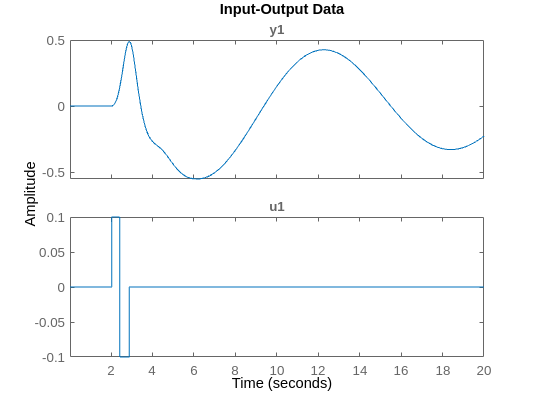

out = sim('el_v',paramStruct);
u = out.elevator;
y = squeeze(out.velocity)-25;
data = iddata(y,u,0.02);
plot(data)

sys_el_v= tfest(data, 3, 2)

sys_el_v =
  From input "u1" to output "y1":
     -5.274 s^2 + 47.16 s + 39.55
  -----------------------------------
  s^3 + 2.008 s^2 + 0.4257 s + 0.5018
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 92.3%                    
FPE: 0.0005525, MSE: 0.0005427                   
 
Model Properties


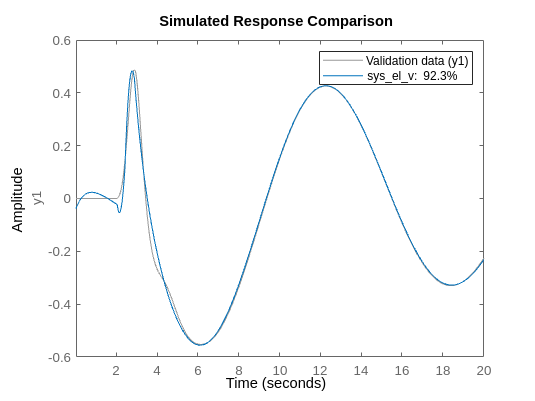

compare(data,sys_el_v)

## elevator to height

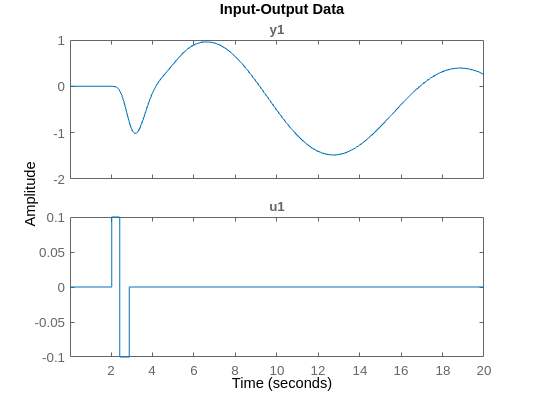

out = sim('el_h',paramStruct);
u = out.elevator;
y = squeeze(out.height)-50;
data = iddata(y,u,0.02);
plot(data)

sys_el_h= tfest(data, 3, 1)

sys_el_h =
  From input "u1" to output "y1":
           84.88 s - 1383
  ---------------------------------
  s^3 + 27.27 s^2 + 1.888 s + 7.101
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 1
   Number of free coefficients: 5
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 49.03%                   
FPE: 0.1399, MSE: 0.1377                         
 
Model Properties


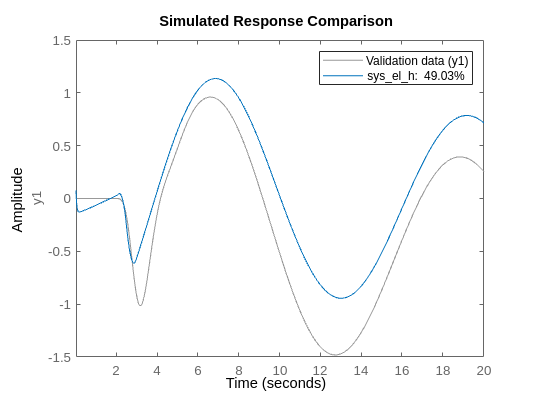

compare(data,sys_el_h)

## elevator to gamma

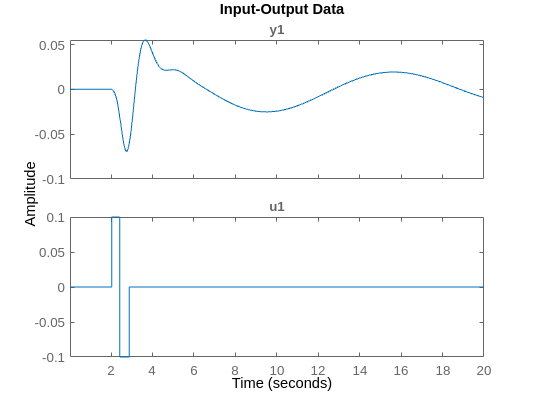

out = sim('el_g',paramStruct);
u = out.elevator;
y = squeeze(out.gamma);
data = iddata(y,u,0.02);
plot(data)

sys_el_g= tfest(data, 3, 2)

sys_el_g =
  From input "u1" to output "y1":
     -0.9671 s^2 + 7.49 s - 114
  ---------------------------------
  s^3 + 10.41 s^2 + 31.14 s + 24.55
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 35.5%                    
FPE: 0.0001651, MSE: 0.0001621                   
 
Model Properties


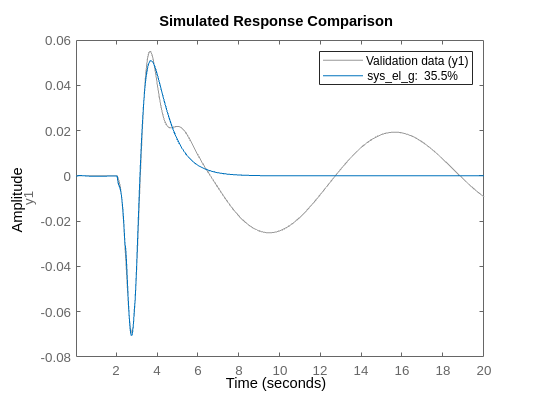

compare(data,sys_el_g)

# Throttle input - short period mode(5secs)

paramStruct.StopTime = "5";

## thrust to pitch rate

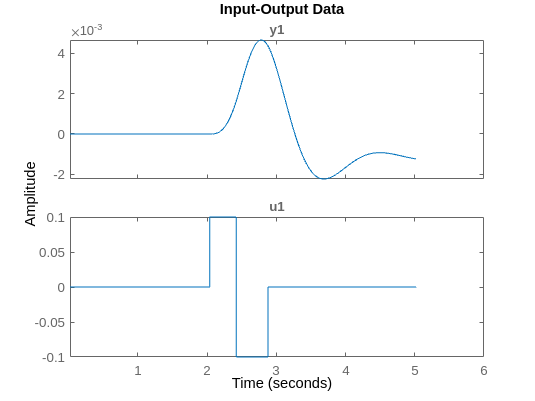

out = sim('t_pr',paramStruct);
u = out.throttle;
y = squeeze(out.pitch_rate);
data = iddata(y,u,0.02);
plot(data)

sys_t_pr= tfest(data, 3, 1)

sys_t_pr =
  From input "u1" to output "y1":
           5.336e-05 s + 2.55
  ------------------------------------
  s^3 + 3.485 s^2 + 15.85 s + 2.53e-12
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 1
   Number of free coefficients: 5
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 91.64%                   
FPE: 1.987e-08, MSE: 1.865e-08                   
 
Model Properties


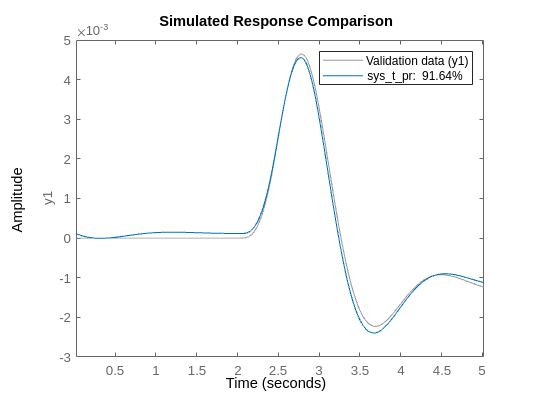

compare(data,sys_t_pr)

## thrust to aoa

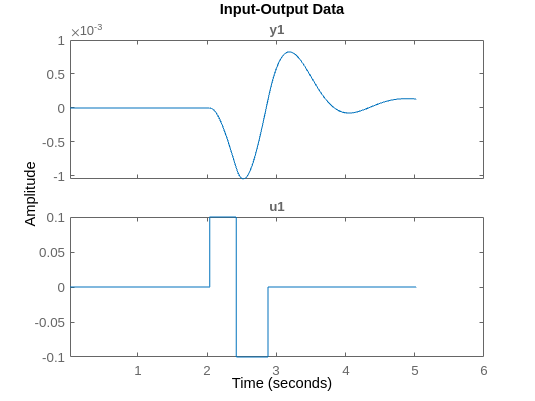

out = sim('t_a',paramStruct);
u = out.throttle;
y = squeeze(out.aoa)-alpha_trim;
data = iddata(y,u,0.02);
plot(data)

sys_t_a= tfest(data, 3,2)

sys_t_a =
  From input "u1" to output "y1":
   -0.0006433 s^2 - 0.1775 s - 0.1927
  ------------------------------------
  s^3 + 3.36 s^2 + 15.81 s + 3.734e-10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 95.76%                   
FPE: 2.511e-10, MSE: 2.337e-10                   
 
Model Properties


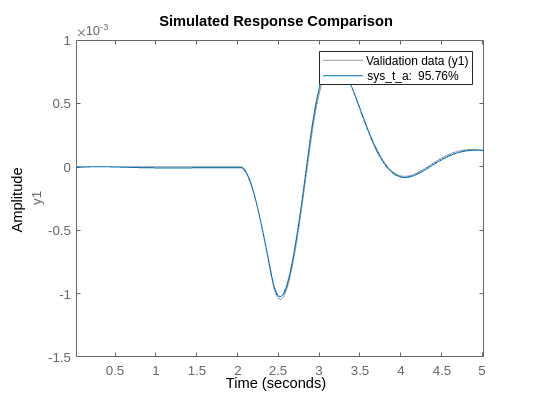

compare(data,sys_t_a)

# Throttle input - phugoid mode(20secs)

paramStruct.StopTime = "20";

## thrust to velocity

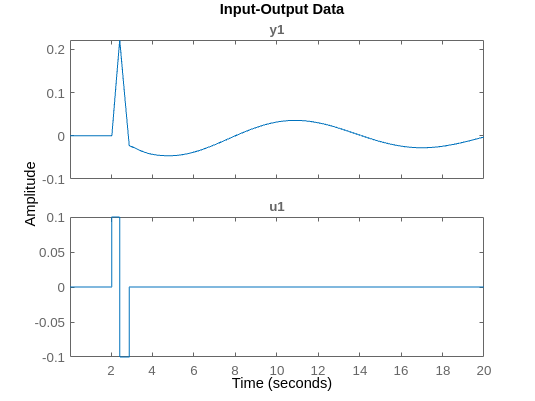

out = sim('t_v',paramStruct);
u = out.throttle;
y = squeeze(out.velocity)-25;
data = iddata(y,u,0.02);
plot(data)

sys_t_v= tfest(data, 3, 2)

sys_t_v =
  From input "u1" to output "y1":
      5.441 s^2 + 2.598 s + 0.6494
  ------------------------------------
  s^3 + 0.2284 s^2 + 0.278 s + 0.03822
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 98.18%                   
FPE: 4.307e-07, MSE: 4.231e-07                   
 
Model Properties


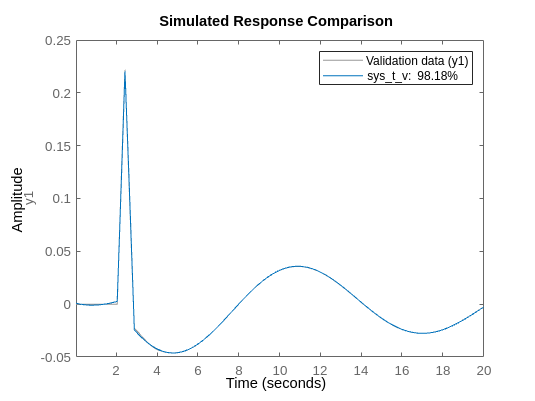

compare(data,sys_t_v)

## thrust to height

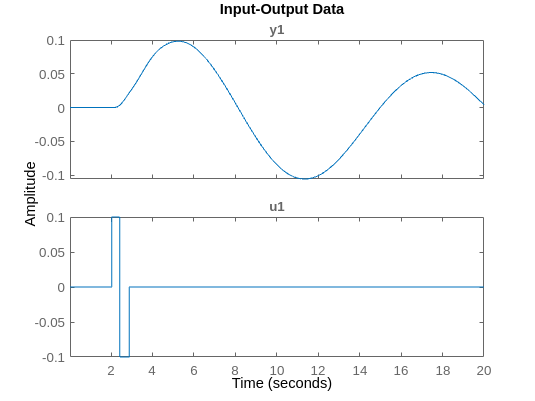

out = sim('t_h',paramStruct);
u = out.throttle;
y = squeeze(out.height)-50;
data = iddata(y,u,0.02);
plot(data)

sys_t_h= tfest(data, 3, 1)

sys_t_h =
  From input "u1" to output "y1":
              -1.093 s + 2.231
  ----------------------------------------
  s^3 + 0.08482 s^2 + 0.2661 s + 2.242e-06
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 1
   Number of free coefficients: 5
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 98.14%                   
FPE: 1.249e-06, MSE: 1.229e-06                   
 
Model Properties


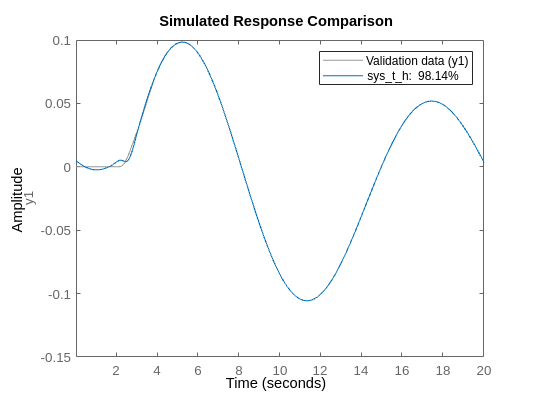

compare(data,sys_t_h)

## thrust to gamma

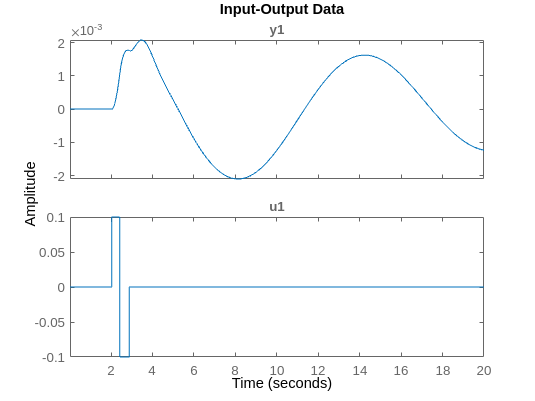

out = sim('t_g',paramStruct);
u = out.throttle;
y = squeeze(out.gamma);
data = iddata(y,u,0.02);
plot(data)

sys_t_g= tfest(data, 3, 2)

sys_t_g =
  From input "u1" to output "y1":
  -0.003332 s^2 + 0.07542 s + 0.1277
  -----------------------------------
  s^3 + 1.098 s^2 + 0.3632 s + 0.2727
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 93.84%                   
FPE: 5.704e-09, MSE: 5.603e-09                   
 
Model Properties


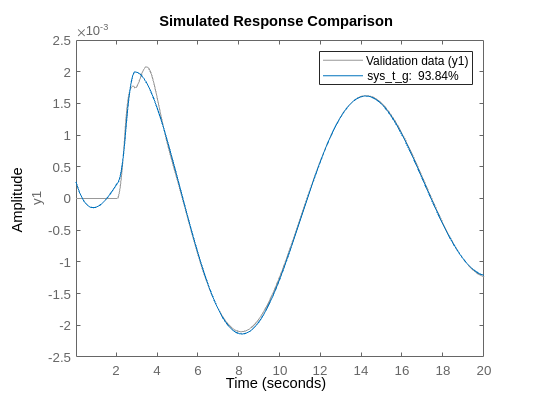

compare(data,sys_t_g)